# Power-Split Hybrid Electric Vehicle Model with Speed Tracking

Copyright 2021 The MathWorks, Inc.

## Open the Model

mdl = "PowerSplitHEV_SpeedTracking";
if not(bdIsLoaded(mdl)), open_system(mdl); end

% Run setup script
PowerSplitHEV_SpeedTracking_setup

## Load Inputs to Workspace

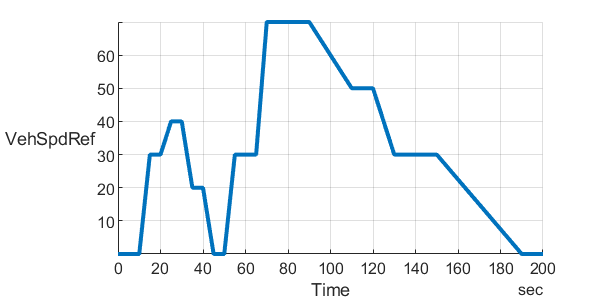

% Vehicle longitudinal velocity reference
fig = figure;
[inputSignals_DrivingPattern, inputBus_DrivingPattern, t_end_1, useKph, useFromWorkspace] = ...
  DrivingPatternBasic_inputs( "PlotParent",fig, "InputPattern","simple_drive_pattern" );

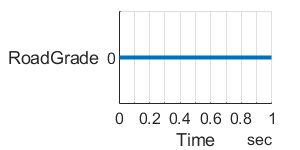

% Road grade
fig = figure;
[inputSignals_RoadGrade, inputBus_RoadGrade, t_end_2] = ...
  DriverAndEnvironment_road_grade_pattern( ...
    "PlotParent",fig, "InputPattern", "flat" );
fig.Position(3:4) = [200 100];  % width height

% Simulation time
t_end = max(t_end_1, t_end_2)

t_end = 200

clear t_end_1 t_end_2

## Run Simulation

% Set initial conditions
initial.driverBrakeForce_N = 8000;
initial.driverBrakeOn_tf = true;
initial.driverHVBattSOC_pct = 99;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override block parameters
drivingPattern.useFromWorkspace_tf = useFromWorkspace;
% clear useFromWorkspace

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Simulation Speed

out.SimulationMetadata.TimingInfo.TotalElapsedWallTime % seconds

ans = 9.6994

t_end  % seconds

t_end = 200

t_end / out.SimulationMetadata.TimingInfo.TotalElapsedWallTime

ans = 20.6197

## Visualize Simulation Result

Vehicle

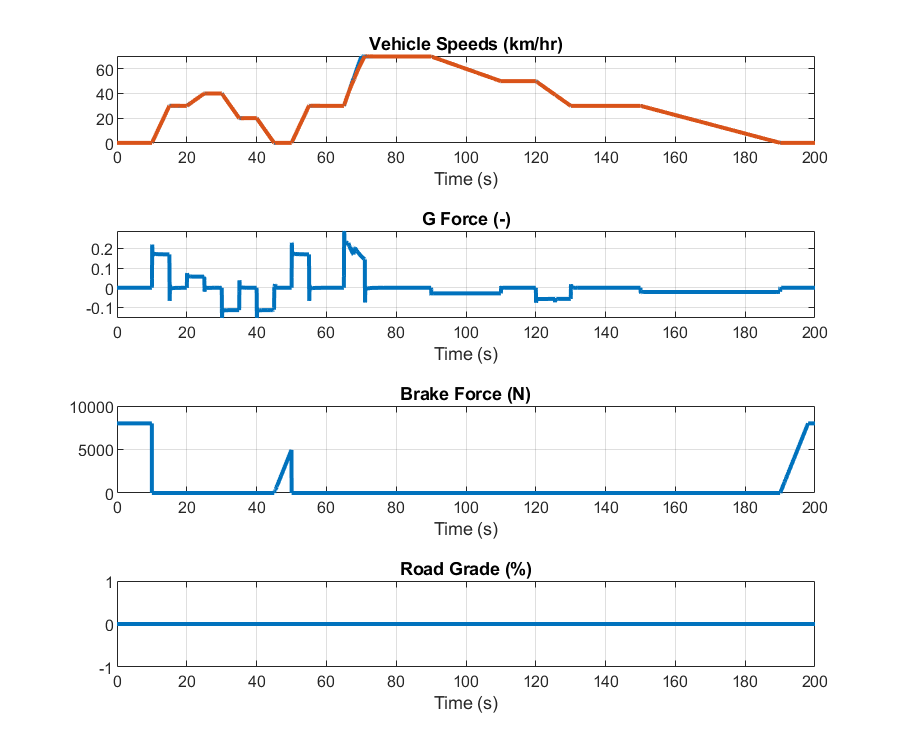

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_vehicle( "Dataset",out.logsout, "PlotParent",fig );

High Voltage Battery

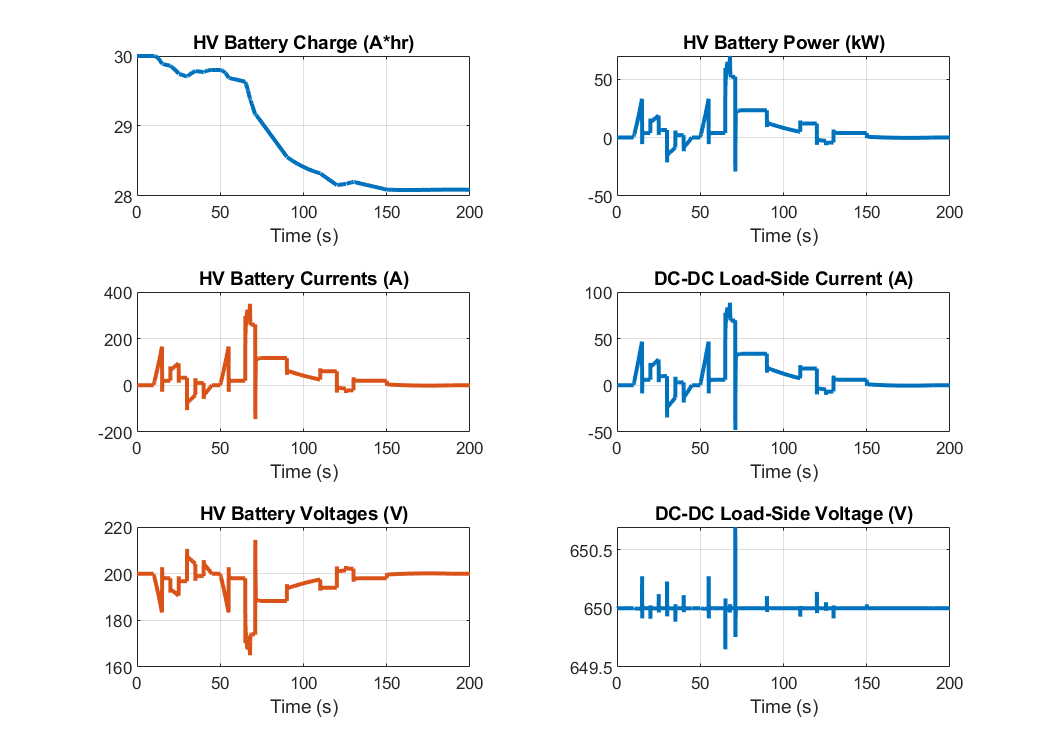

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_hvbattery( "Dataset",out.logsout, "PlotParent",fig );

Power-Split Drive Unit

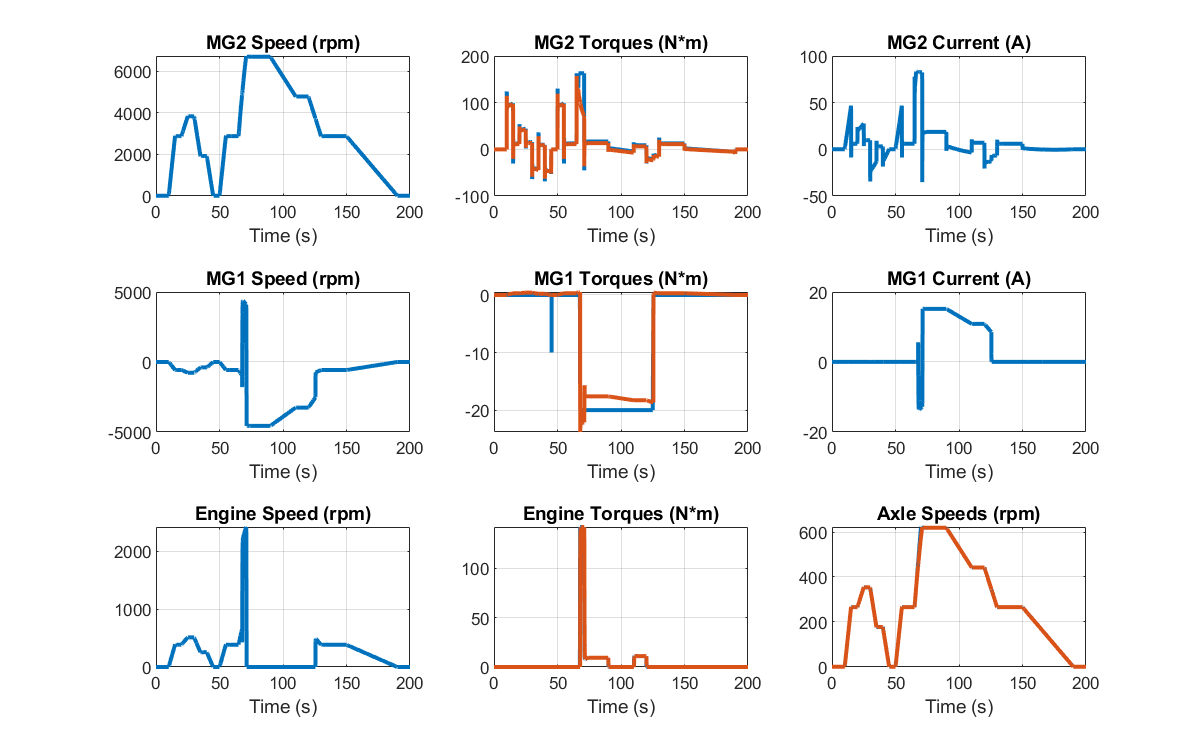

fig = figure;
PowerSplitHEV_SpeedTracking_plot_result_powersplit( "Dataset",out.logsout, "PlotParent",fig );